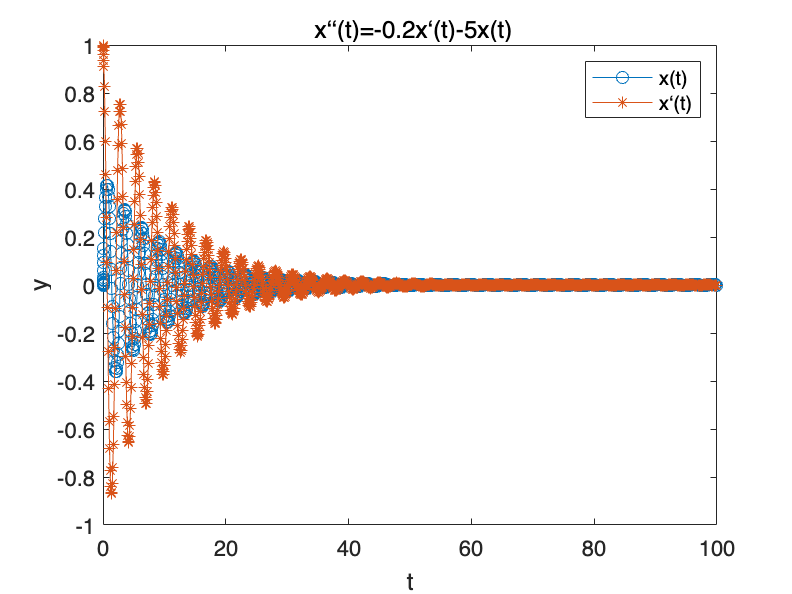

clc
clear all
close all

tspan=[0 100.0]; %求解区间
y0=[0 1]; %初值
[t,x]=ode45(@odefun,tspan,y0);
plot(t,x(:,1),'-o',t,x(:,2),'-*')
legend('x(t)','x‘(t)')
title(' x‘‘(t)=-0.2x‘(t)-5x(t)')
xlabel('t')
ylabel('y')

function y=odefun(t,x)
y=zeros(2,1); % 列向量 %x(1)= x ,y(1)= x(2) = x',y(2) = x'';
y(1)=x(2);
y(2)=-5*x(1)-0.2*x(2);
end

